# Reduced modulus to elastic modulus converter

Elastic modulus is determined through the expression shown below. Subindex "i" refers to the indenter, while "m" to the material. For diamond tips, Poisson = 0.07 and E = 1140 GPa.

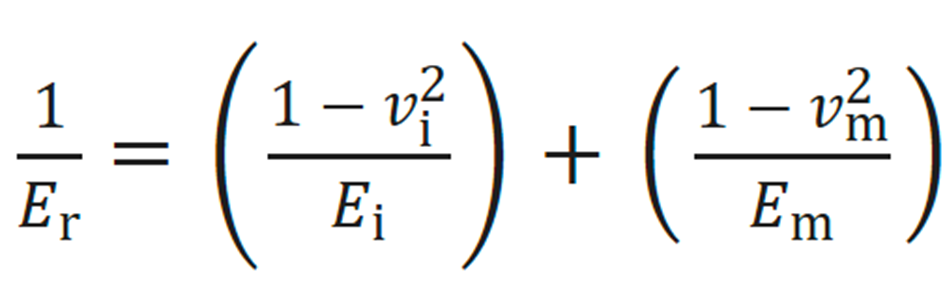

ReducedMod_GPa = 400; % Reduced modulus measured by FemtoTools nanoindenter [GPa]
Poisson_m = 0.3; % Poisson value of the tested material
E_i = 1140; % Elastic modulus of the nanoindenter tip [GPa] (1140 GPa for diamond)
Poisson_i = 0.07; % Poisson value of the nanoindenter tip (0.07 for diamond verkovich)
materialmodulus_GPa = ((1-Poisson_m^2).*(E_i.*ReducedMod_GPa))/(E_i-(ReducedMod_GPa.*(1-Poisson_i^2)));

fprintf('Elastic modulus of the material is %.2f GPa\n', materialmodulus_GPa);

Elastic modulus of the material is 559.28 GPa
